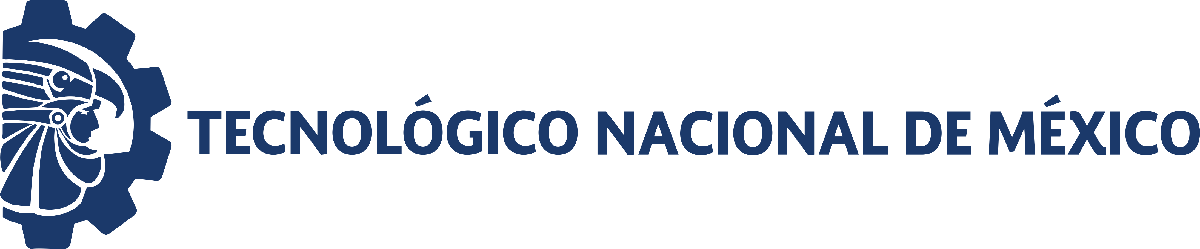                                 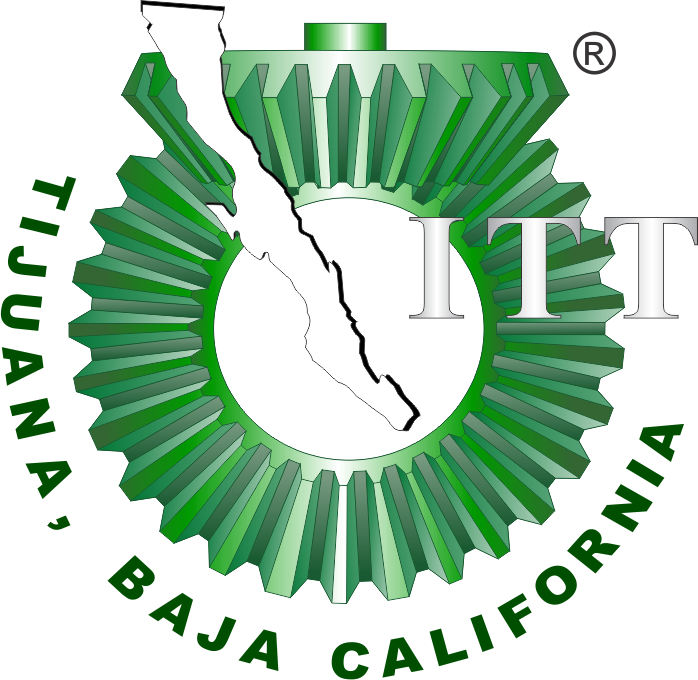

# Práctica 2: Mecanica Pulmonar

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

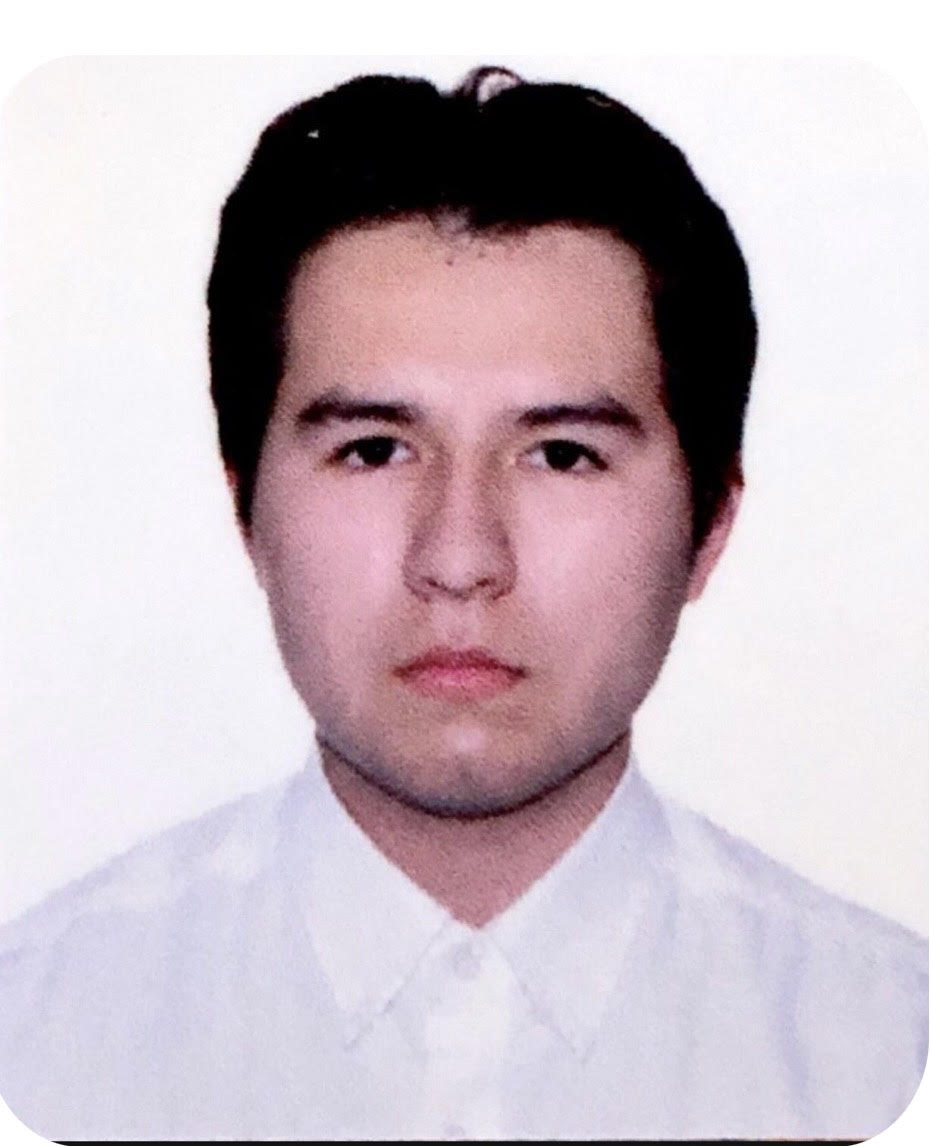

Nombre del alumno: Angel Eduardo Juarez Salazar

Número de control: 22210417

Correo institucional: l22210417**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '30';
file = 'Juarez_22210417';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';
Controlador = 'PID';

## Rendimiento del controlador

kP= Rr/Re 

kl= 1/Re*Cr

kD=Rr*Ce

Settling time = 0.00226

Overshoot=0.705%

Peak=1.01

## Respiracion normal

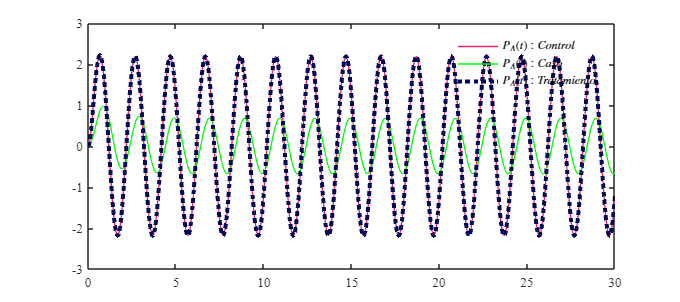

Signal = 'Respiracion normal';
set_param('Juarez_22210417/Pao(t)','sw','1');
set_param('Juarez_22210417/PID Controller','P','156.6');
set_param('Juarez_22210417/PID Controller','I','2478.4');
set_param('Juarez_22210417/PID Controller','D','0.85');
N = sim(file,parameters);
plotsignals(N.t,N.PAx,N.PAy,N.PAz,Signal)

##     Respiracion anormal

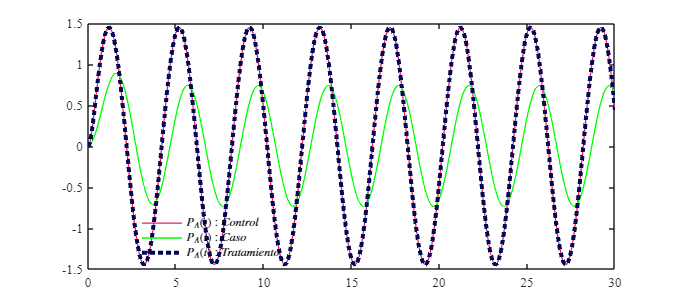

Signal = 'Respiracion anormal';
set_param('Juarez_22210417/Pao(t)','sw','0');
set_param('Juarez_22210417/PID Controller','P','156.6');
set_param('Juarez_22210417/PID Controller','I','2478.4');
set_param('Juarez_22210417/PID Controller','D','0.85');
N = sim(file,parameters);
plotsignals(N.t,N.PAx,N.PAy,N.PAz,Signal)

## Funcion:Respuesta a las señales

function plotsignals(t,PA,Pao,PID,Signal)
set(figure(),'Color','w')
set(gcf,'Units','Centimeters','Position',[1,1,18,8])
set(gca,'FontName','Times New Roman')
fontsize(10,'points')
red = [232/255, 37/255,97/255];
blueR = [0, 9/255, 87/255];
green = [0, 255/255, 0];
hold on; grid off; box on;

plot(t,PA,'LineWidth',1,'Color',red)
plot(t,Pao,'LineWidth',1,'Color',green)
plot(t,PID,':','LineWidth',3,'Color',blueR)

L= legend('$P_{A}(t):Control$','$P_{A}(t):Caso$','$P_{A}(t):Tratamiento$');
set(L, 'Interpreter','Latex','Location','Best','Box','off')

end
